# Identifying artefact in infant brainwave recordings using machine learning: a demonstration

## Introduction

Electroencephalography (EEG) is a method of measuring brain activity by recording electrical activity that "leaks" from the brain into the scalp. It is used frequently in neuroscience research, and - like all methods of recording - it's important to separate artefact from the signal that you're trying to record. Currently, in neuroscience on infants, this identification is not done in a reproducible way. This is because it is difficult to use established, automated methods on infants, and no automated methods exist for infants. We can make one, though, with a sprinkle of machine learning. **Here I will demonstrate an automated, reproducible method of identifying artefact in EEG signals from infants.**

Currently, in neuroscience research on very young infants, this separation of artefact from signal is done manually by a person. You can see this in the reporting which published articles give. A great many articles do not tell us how they decided what was artefact (for example [Slater 2010](https://doi.org/10.1016/j.ejpain.2009.05.005), [Norman 2008](https://www.nature.com/articles/pr2008220), [Slater 2010,](https://doi.org/10.1016/j.neuroimage.2010.04.253) [Fabrizi 2011](https://doi.org/10.1016/j.cub.2011.08.010), [Hartley 2015](https://www.nature.com/articles/srep12519), but this list is not exhaustive and not intended to criticise these authors, as this is very much standard across the field!). Some use manual methods and record the methods used: [Verriotis 2015](https://dx.doi.org/10.1097%2F01.j.pain.0000460302.56325.0c) says that a neurophysiologist assessed traces "as normal [...] with respect to symmetry, synchronicity, absence of epileptiform activity, and background rhythms appropriate for age". [Slater 2010](https://doi.org/10.1016/S0140-6736(10)61303-7) uses a 50uV/50ms (in >15 electrodes) ceiling, rejecting anything above that as movement artefact. [Maimon 2013](https://www.academia.edu/download/43888519/Electroencephalographic_Activity_in_Resp20160319-2258-18319so.pdf) uses this manual method: view 30-sec increments of 0.3-75Hz bandpassed average of the electrodes Fp1, Fp2, Pz, C1, C2 and accept anything "free of movements and electrical induction artefact".

In this short demonstration I will show you a method of automatically detecting artefact in EEG from babies. In order to do this, we have three main design requirements.

- The method must be usable in matlab, as neuroscientists tend to use this.

- The method must be automated and require no human judgement, for best reproducibility.

- The method must be usable with a single EEG channel, as some research on infants uses this.

- The method must be usable on a single short period ("epoch") of data, allowing use on individal infants.

## Existing methods in other areas of neuroscience

There are several exceptional open-source artefact-detection methods for EEG already available. These are widely used in adult neuroscience research. Some of these, like Independent Component Analysis (ICA, e.g. see [Klug & Gramann 2021](https://doi.org/10.1111/ejn.14992)), require human intervention in their default use. This clearly doesn't meet design requirement #2. Other methods include:-

### Extreme Standardised Deviate

The [OSL](https://ohba-analysis.github.io/osl-docs) uses generalised [ESD](https://doi.org/10.2307/1268549) (extreme studentised deviate test, aka maximum normalised residual test or Grubbs's test). This uses the test statistic:-


$$G = \frac{max_{i=1,...,N}|Y_i-\bar{Y}|}{s}$$


Where s is the standard deviation and Y is the sample data. It measures the largest absolute deviation from sample mean, in units of number of standard deviations. The generalised version of this test tests to a set limit (the original version tests a set number of expected outliers, instead). Typically this test is run with a user-defined acceptance threshold, and run recursively, removing the $Y_i$ identified by max each time until the test statistic G is below the set threshold (eg. below 3 SDs from sample mean). The OSL calculates the SD (or other summary metric, at users' discretion) for each epoch and then apply generalised ESD to see which of the epochs as a whole is an outlier (in terms of, it's signal SD is an outlier compared to the average signal SD from all epochs). 

Because it uses a set of epochs, ESD contradicts design requirement #3 or #4, depending on how you group your epochs.

### Artefact Subspace Reconstruction

[EEGlab](https://eeglab.org/) uses [ASR](https://github.com/sccn/clean_rawdata) (good wiki in that repo) as described in [this paper](https://www.ncbi.nlm.nih.gov/pubmed/26415149). It does this:-

- Remove flat lines >5sec and channels poorly correlated (R<0.85) with adjacent channels (we can't use this due to limited channels but if we could, need to label channels). Optionally highpass filter if not done already.

- Take a 60-sec clean resting-state period (manual or automatic) of EEG data as calibration. Split data to check into 1-sec periods.

- PCA splits signal into components, and for each calibration component a Normal curve is made for amplitudes.

- For each component in each test segment, amplitude of component is compared to calibration curve.

- More than a user-set threshold of 3 SDs (aggressive) - 100SDs (lax) from the calibration mean is considered an artefact. [Chang et al ](https://www.researchgate.net/publication/325921646_Evaluation_of_Artifact_Subspace_Reconstruction_for_Automatic_EEG_Artifact_Removal)suggest a threshold of 10-20.

- Signals can be reconstructed by mixing signals back in without the offending principal component (hence the name subspace reconstruction), but we don't want that.

The rationale for this is to identify occasional, large-amplitude artefacts. This is distinct from identifying constant noise, which the creators advise using ICA for. ASR uses the correlation between different EEG channels, and so contradicts design requirement #3.

## Potential predictors of artefact

Once we remove all of the potential predictors of artefact involving the spatial domain (i.e. location in the head, which contravenes our requirement #3) and comparisons between different infants (requirement #4), we are left with two possible domains which we can draw predictors (also known as features) from, shown below.

### Time-domain features

- Voltage amplitude change within window. This is already used unofficially, and reported in Slater 2010 and Schmidt-Mellado 2022. Gabi's paper uses a 800uV threshold anywhere pre-stimulus.

- Extreme Studentised Deviate (see [[EEG artefact detection pipelines#ESD Extreme Studentised Deviate]]). The benefit of this method is that it does not rely on spatial knowledge. The drawback is that it uses a whole set of epochs as baseline. You could possibly use a known base set of EEG epochs as the comparative group for a single new epoch, but you make the assumption that the these are equivalent.

- Mean local skewness 15sec. This is the third most well-correlated feature in the MARA method (see [[EEG artefact detection pipelines#MARA]]). Mean absolute local skewness of any given 15-second segment. Note that this is run on an IC in MARA, and was not tested on whole-data EEG.

- Temporal kurtosis. High temporal kurtosis indicates sudden changes in voltage amplitude, which is associated with blinks in EEG. Chosen by FASTER (see [[EEG artefact detection pipelines#FASTER Fully Automated Statistical Thresholding for EEG artifact Rejection]]) as a particularly explainable feature. Note that this was tested on ICs, so might not work when the artefact components are still intermixed in the signal. Mognon also uses this.

- Maximum local variance. According to [Mognon 2011](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.434.798&rep=rep1&type=pdf), eye movements and other generic discontinuities often give slower EEG voltage changes than blinks so are difficult to detect using kurtosis. They do change the EEG voltage, however, so Mognon argues that they can be detected using maximum voltage variance within an epoch. Notably, this code (ADJUST.m lines 241-279) is performed on ICs so it finds the max variance of any IC, and normalises to the mean variance across all ICs. In this way it's not really looking for the absolute magnitude of this variance, inasmuch as it looks for a single IC which has a variance much higher than other ICs. 

### Frequency-domain features

- Alpha-band power. This is the fifth most well-correlated feature in the MARA method (see [[EEG artefact detection pipelines#MARA]]). Average log band power of $\alpha$ (8-13Hz) spectrum band.

## What is the truth?

The truth is a tricky thing! Whenever we carry out [supervised machine learning](https://en.wikipedia.org/wiki/Supervised_learning), we need a "ground truth": a set of data representing our expected result. In this case, our ground truth is a set of labels on EEG epochs, labelling each one "artefact" or "not artefact". A supervised ML algorithm can only emulate its ground truth, so it's important that our "ground truth artefacts" are as accurate as possible. But how do we know what artefact is, when there isn't already a method of identifying artefact in this type of data?

Fortunately, we have some very skilled neuroscientists who are experienced at identifying artefactual signals. Even more fortunately, they are quite obliging people. I got 7 of them to look at over 250 examples of EEG epochs, recorded from very young babies born in Oxford between 2010 and 2022. These examples each cover 2 seconds of EEG data, recorded at 2kHz on the Cz electrode. Some of the examples record the baby at rest, while others record responses to a variety of stimuli (touch, light, sound, and pain). All of the examples are fully pseudonymised, both to the neuroscientists participating and in this repository; the recordings themselves are not included here to maintain anonymity. 

Each neuroscientist was given an online questionnaire to fill out, as the picture below. The results are recorded in a table, imported below.

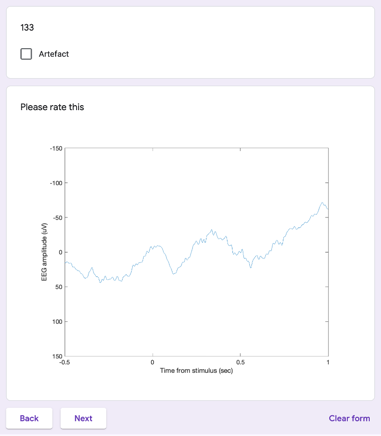

opts = spreadsheetImportOptions("NumVariables", 8);
opts.Sheet = "1&2 (short epochs)";
opts.DataRange = "A3:H281";
opts.VariableNames = ["Pseudo", "A", "B", "C", "D", "E", "F", "G"];
opts.VariableTypes = ["string", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical", "categorical"];
opts = setvaropts(opts, "Pseudo", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Pseudo", "A", "B", "C", "D", "E", "F", "G"], "EmptyFieldRule", "auto");

artefact_tbl = readtable("/Users/simon/Documents/Code/Demo-artefact-detector/Questionnaire results.xlsx", opts, "UseExcel", false);
clear opts


"Pseudo" is the pseudonymisation key for each epoch of EEG data; neuroscientist raters are labelled A-G. Raters A-D are "novice" (postgraduate students), and raters E-G are "experienced" (postdoctoral).

artefact_tbl(1:5,:)

ans = 5×8 table
    Pseudo      A         B           C          D         E          F         G    
    ______    _____    ________    ________    _____    ________    _____    ________

    "280"     Clean    Clean       Clean       Clean    Clean       Clean    Clean   
    "281"     Clean    Clean       Clean       Clean    Clean       Clean    Clean   
    "282"     Clean    Artefact    Artefact    Clean    Artefact    Clean    Artefact
    "278"     Clean    Clean       Clean       Clean    Clean       Clean    Clean   
    "279"     Clean    Clean       Clean       Clean    Clean       Clean    Clean   


### Inter-rater reliability

We need to know how reliable raters are in order to compare our algorithm to humans later on. As there is no definite "truth" to artefact detection, we assess the inter-rater reliability of human raters, which we do using Krippendorf's alpha. This statistic goes between 0 (agreement between raters is no better than chance) and 1 (perfect agreement between raters).

num_of_raters = width(artefact_tbl)-1; 
krip = krippendorff(artefact_tbl{:,2:num_of_raters+1}=='Artefact', 'nominal')

krip = 0.5282

Use cohen's kappa (which compares 2 raters with one another) to compare each rater with each other rater, and so work out how far they are from the group average. Cohen's kappa is good here because it adjusts for the probability of two raters agreeing by pure chance, which is high (50%) when there are only two categories as here. In the same way as Krippendorf, above, it is between 0 (no better than chance) and 1 (perfect agreement).

rater_comps = NaN(num_of_raters);
for n=1:num_of_raters
    col = n+1;
    for m=1:num_of_raters
        if n~=m
            rater_comps(n,m) = cohensKappa(artefact_tbl{:,col},artefact_tbl{:,m+1});
        end
    end
end
rater_comps = array2table(rater_comps,'VariableNames',artefact_tbl.Properties.VariableNames(2:end));
rater_comps.Avg = mean(rater_comps{:,:},2,'omitnan');
rater_comps

rater_comps = 7×8 table
       A          B          C          D          E          F          G         Avg  
    _______    _______    _______    _______    _______    _______    _______    _______

        NaN    0.32172    0.40439    0.52599    0.53403    0.76235    0.78178    0.55505
    0.32172        NaN     0.5401    0.48196    0.53595    0.40244    0.41111    0.44888
    0.40439     0.5401        NaN     0.5113    0.47525    0.50063    0.49506    0.48779
    0.52599    0.48196     0.5113        NaN    0.57124    0.73617    0.57889    0.56759
    0.53403    0.53595    0.47525    0.57124        NaN    0.60697    0.64464    0.56135
    0.76235    0.40244    0.50063    0.73617    0.60697        NaN    0.75369   

By comparing pairwise like this, we get a person-by-person measure of agreement with the group overall.

clear n m col

Here is the breakdown of how many epochs have strong agreement (no or one dissenting raters) vs weak agreement.

histogram(sum(artefact_tbl{:,2:end}=='Artefact',2))
title('Rater agreement histogram')
ylabel('Number of epochs rated')
xlabel('Number of raters labelling "artefact"')

Here is the breakdown of how raters agree with one another, including experienced ('old') vs novice ('new') raters. As you can see, the experienced group agree more amongst themselves ($\kappa=0.67$) than the novice group is ($\kappa=0.46$). Over the whole group, agreement is 0.55, which is "fair" inter-rater reliability ([Chichetti & Sparrow 1981](https://psycnet.apa.org/record/1982-00095-001)). In cases like this where each individual is better than chance but less than perfect, and the group is not in complete agreement, a group judgement will be better than that of any individual, however expert that individual is (Valentini and Masulli, 2002). Because of this, for each epoch we will take the group judgement (the mode).

heatmap(rater_comps{:,1:end-1}, ...
    'ColorLimits',[0,1], ...
    'XDisplayLabels',{'A','B','C','D','E','F','G'}, ...
    'YDisplayLabels',{'A','B','C','D','E','F','G'})
xlabel('Rater ID')
title("Cohen's kappa agreement between individual raters")

experiencedraters = [5,6,7]; noviceraters = [1,2,3,4];
experienced_agreement = mean(rater_comps{experiencedraters,experiencedraters},'all','omitnan')

experienced_agreement = 0.6684

novice_agreement = mean(rater_comps{noviceraters,noviceraters},'all','omitnan')

novice_agreement = 0.4642

average_agreement = mean(rater_comps{:,1:end-1},'all','omitnan')

average_agreement = 0.5512

## Predictor evaluation

As I don't include raw data here, I have pre-calculated the predictors which I described earlier.

load("artefacts.mat","artefacts");
artefacts(1:5,:)

ans = 5×17 table
    Pseudo          ID         Epoch             Type                 A           B           C           D           E           F           G         Group      LogVariance     Skew      Kurtosis    DeltaV    LogAlphaPower
    _______    ____________    _____    _______________________    ________    ________    ________    ________    ________    ________    ________    ________    ___________    _______    ________    _____

Check for any correlation of potential predictors with the response variable, visually using boxplots and numerically using logistic regression. 

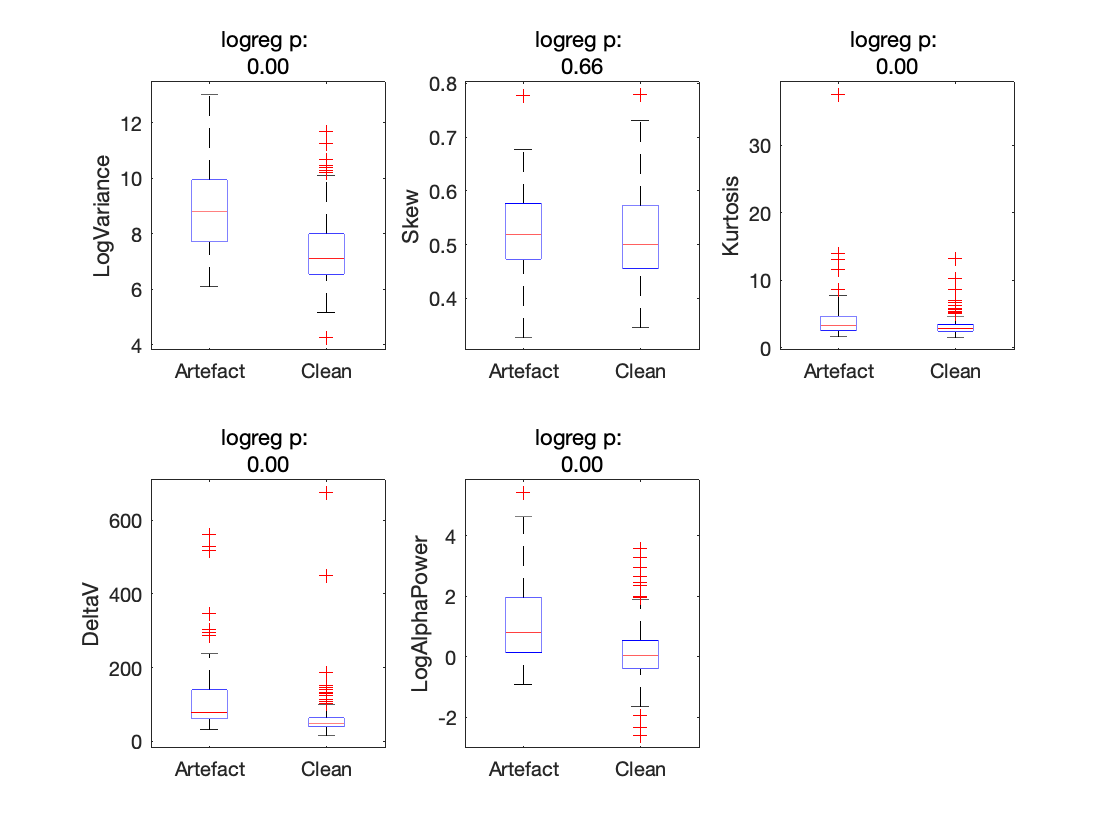

figure
featurenames = {'LogVariance','Skew','Kurtosis','DeltaV','LogAlphaPower'};
for n=1:length(featurenames)
    subplot(2,3,n)
    feat = featurenames{n};
    boxplot(artefacts.(feat), artefacts.Group, 'Labels', categories(artefacts.Group))
    ylabel(feat)
    [~,~,stats] = mnrfit(artefacts.(feat), categorical(artefacts.Group));
    subtitle({'logreg p: ',num2str(stats.p(2),'%.2f')})
end

Next, we check for correlation of predictors with one another. A pairwise correlation plot will show these. This uses a script, kept in this repository, which I've modified this to show plots for small datasets and colourmaps for larger ones. If two or more predictors correlate very highly with another, this can create a multicollinearity problem, where variables are not necessarily fully independent of one another. Ths would make it difficult to differentiate between the effects of these variables, an issue which we would need to address. Some level of correlation between predictors is fine, as long as there is some independence between variables. All of the predictors shown here are fine.

Here we also check the distribution of predictors. Here Kurtosis and DeltaV look like they could do with a log to create a more normal distribution, but only some methods (eg. k-nearest-neighbours) assume normality. We will use a random forest method, which does not assume normality, so this is fine.

figure
corrplot = pairwise_corr_plot(artefacts{:,13:17},artefacts.Properties.VariableNames(:,13:17));
sgtitle('Pairwise correlation plot')

## Model training

Now for the moment I'm sure you've been waiting for; we're going to train our model. In order to properly test it later, we'll first split off a test set, testing_data, which we will not touch.

rng('default') % For reproducibility
hpartition = cvpartition(height(artefacts),'Holdout',0.2);
training_data = artefacts(training(hpartition),:);
testing_data = artefacts(test(hpartition),:);

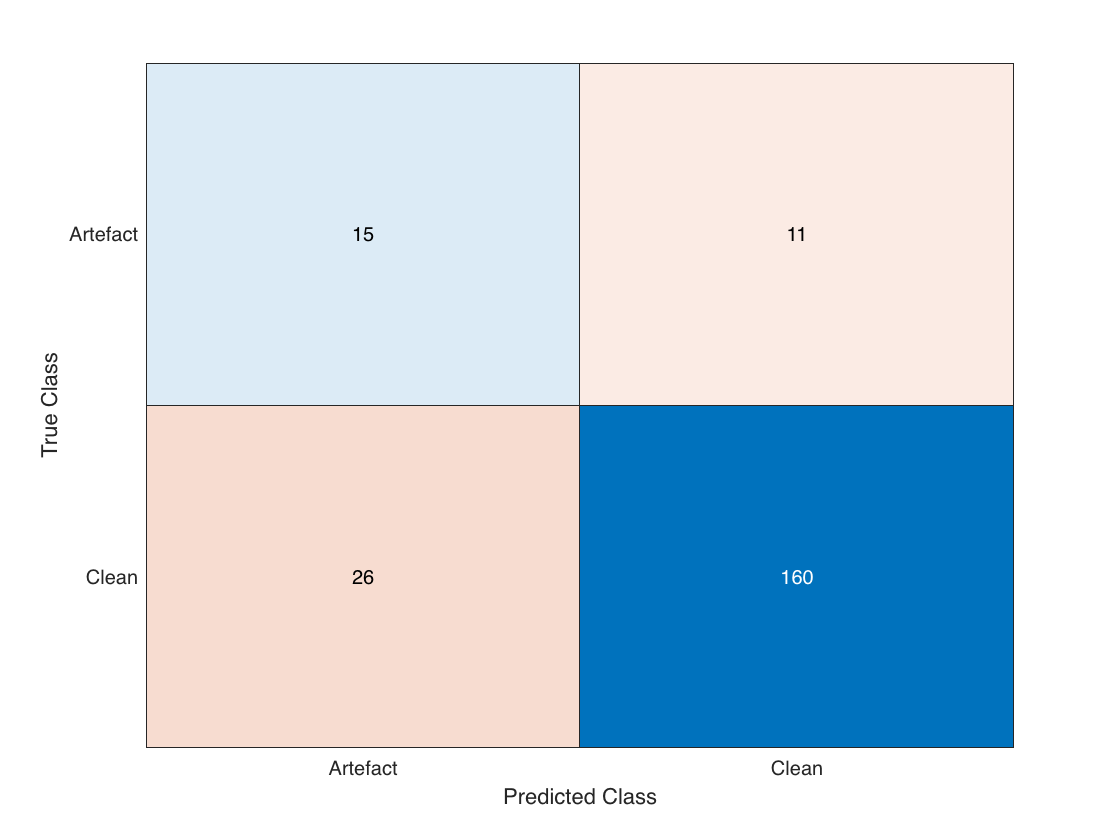

[trainedClassifier, validationAccuracy, balancedAccuracy] = trainRF(training_data);

The balanced accuracy (sensitivity+specificity/2) is more helpful than the accuracy here, as the datatset is biased (there being much fewer artefacts than clean data).

balancedAccuracy

balancedAccuracy = 0.7186

## Model evaluation

To evaluate the model with reference to our human raters, we can evaluate every rater using the held-out test set, including our shiny new machine rater.

testing_data.ModelOutput = categorical(trainedClassifier.predictFcn(testing_data));

% Calculate cohen's kappa for our raters
raters = {'A','B','C','D','E','F','G','ModelOutput'};
rater_comps = NaN(length(raters));
for n=1:length(raters)
    col = raters{n};
    for m=1:length(raters)
        if n~=m
            col2 = raters{m};
            rater_comps(n,m) = cohensKappa(testing_data{:,col},testing_data{:,col2});
        end
    end
end
rater_comps = array2table(rater_comps,'VariableNames',raters);
rater_comps.Avg = mean(rater_comps{:,:},2,'omitnan');
rater_comps

rater_comps = 8×9 table
       A          B          C          D          E          F          G       ModelOutput      Avg  
    _______    _______    _______    _______    _______    _______    _______    ___________    _______

        NaN    0.29123    0.31064    0.55781    0.68415    0.70637    0.85319      0.30161      0.52928
    0.29123        NaN     0.5068    0.49375    0.49375    0.37278    0.37278      0.25352       0.3978
    0.31064     0.5068        NaN    0.52252    0.52252    0.39636    0.39636      0.11128      0.39521
    0.55781    0.49375    0.52252        NaN    0.56911    0.82274     0.5864      0.26728      0.54566
    0.68415    0.49375    0.52252    0.56911 

If we take the novice raters, we can see that already our model is approaching their accuracy.

novice_agreement = mean(rater_comps.Avg(1:4))

novice_agreement = 0.4670

model_agreement = rater_comps.Avg(end)

model_agreement = 0.2947

There are many ways of improving this model, and I intend to follow them. For now though, this is left - as they say - to the reader.